## 对数据预处理

% 最后两列数据是-Inf，删除
plot_A_DT = plot_A_DT(:, 1:end-2);
plot_A_DT2 = plot_A_DT2(:, 1:end-2);
% 删除零频附近的值
plot_A_DT(101, :) = []
plot_A_DT2(101, :) = []

## 环境参数定义

% 定义收发机位置
xR2 = -0.7;
yR2 = -0.7;
d = 2.5;

% vNow的下界为0，thetaNow的下界为0
lb = [0, 0]; 
% vNow的上界为10，thetaNow的上界为pi
ub = [5, 2*pi]; 

## 迭代求解速度、角度和位置

% 迭代步长
N0 = 1;
% 迭代次数
max_iter = length(array_start_time)-2;
tValues = 1:max_iter;
% 收敛容差
tolerance = 1e-6; 

## 初始化运动过程

% 初始化当前位置
xArray = [-0.7];
yArray = [-0];

% 初始化当前速度和角度
vArray = [0.3];
thetaArray = [pi/6];

f1Array = [-40];
f2Array = [140];

## 迭代过程

for iter = tValues
    xNow = xArray(iter);
    yNow = yArray(iter);

    % 计算三个角度
    phi1Now = atan(yNow / xNow);
    phi2Now = atan((yNow - yR2) / (xNow - xR2));
    phiNow = atan(yNow / (xNow - d));

    vNow = vArray(iter);
    thetaNow = thetaArray(iter);

    % 得到多普勒频移最大值及其位置
    array1Now = plot_A_DT(:,iter);
    [maxValue1, maxIndex1] = max(array1Now);
    f1Now = customFunction(maxIndex1);
    
    array2Now = plot_A_DT2(:,iter);
    [maxValue2, maxIndex2] = max(array2Now);
    f2Now = customFunction(maxIndex2);
    
    % 求解方程组，估测速度v和角度theta
    % f1Now = -2 * f_c / c * vNow * cos(thetaNow - (phi1Now + phiNow) / 2) * cos((phi1Now - phiNow) / 2);
    % f2Now = -2 * f_c / c * vNow * cos(thetaNow - (phi2Now + phiNow) / 2) * cos((phi2Now - phiNow) / 2);
    
    % 定义目标函数
    objective = @(x) norm([
        -2 * f_c / c * x(1) * cos(x(2) - (phi1Now + phiNow) / 2) * cos((phi1Now - phiNow) / 2) - f1Now;
        -2 * f_c / c * x(1) * cos(x(2) - (phi2Now + phiNow) / 2) * cos((phi2Now - phiNow) / 2) - f2Now
    ]);
    % 定义初始猜测值
    initialGuess = [vNow, thetaNow];
    
    % 使用 fmincon 求解带约束的非线性方程组
    options = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'sqp');
    solution = fmincon(objective, initialGuess, [], [], [], [], lb, ub, [], options);
    vNow = solution(1);
    thetaNow = solution(2);

    % 计算新位置
    xNext = xNow + vNow * step_dop * Ts * cos(thetaNow);
    yNext = yNow + vNow * step_dop * Ts * sin(thetaNow);
     
    xArray = [xArray, xNext];
    yArray = [yArray, yNext];

    vArray = [vArray, vNow];
    thetaArray = [thetaArray, thetaNow];

    f1Array = [f1Array, f1Now];
    f2Array = [f2Array, f2Now];
end

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.460246e+02     0.000e+00     1.000e+00     0.000e+00     1.420e+00  
    1           6    1.456022e+02     0.000e+00     1.000e+00     4.316e-01     1.093e-01  
    2           9    1.456022e+02     0.000e+00     1.000e+00     0.000e+00     0.000e+00  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

## 输出结果

xArray

xArray =    -0.7000   -0.7000   -0.7000   -0.7000   -0.7000   -0.7000   -0.7000   -0.7000   -0.6999   -0.6999   -0.6999   -0.6999   -0.6998   -0.6998   -0.6998   -0.6997   -0.6997   -0.6997   -0.6996   -0.6996   -0.6996   -0.6996   -0.6996   -0.6996   -0.6996   -0.6996   -0.6996   -0.6996   -0.6996   -0.6996   -0.6996   -0.6996   -0.6996   -0.6996   -0.6996   -0.6995   -0.6995   -0.6995   -0.6995   -0.6995   -0.6995   -0.6994   -0.6994   -0.6994   -0.6993   -0.6993   -0.6992   -0.6992   -0.6992   -0.6991


yArray

yArray =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



vArray

vArray =     0.3000         0         0         0         0         0         0    4.8000    3.5992         0    2.3987    2.3984    5.0000    5.0000         0    5.0000    2.3948    2.3943    2.3939    2.3935    2.3930         0         0         0         0         0    1.1935    1.1933    1.1931    1.1929         0         0         0         0         0    1.1943    1.1942    1.1940    1.1938    1.1937    1.1935    3.5927    3.5922    4.7923    4.7917    4.7910    2.3889    2.3885    5.0000    5.0000


thetaArray

thetaArray =     0.5236    0.2133    0.2133    0.2133    0.2133    0.2133    0.2133         0         0    0.0032         0         0         0         0    0.0055         0         0         0         0         0         0    0.0018    0.0018    0.0018    0.0018    0.0018         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0



f1Array

f1Array =    -40   -40   -30   -60   -40   -40   -40   -60   -60   -40   -50   -50   -70   -70   -40   -60   -60   -60   -60   -60   -60   -50   -50   -50   -50   -50   -50   -50   -50   -50   -30   -30   -40   -30   -30   -40   -40   -40   -40   -40   -40   -50   -50   -50   -50   -50   -50   -50   -70   -70


f2Array

f2Array =    140   140   100   100   130    80    90    80    90    80    80    80    80    80    80    70   100   100   100   100   100   100   100   100   100   100    90    90    90    90    90    90    90    60    60    70    70    70    70    70    70    70    70    60    60    60    80    80    80    80


## 绘制运动轨迹

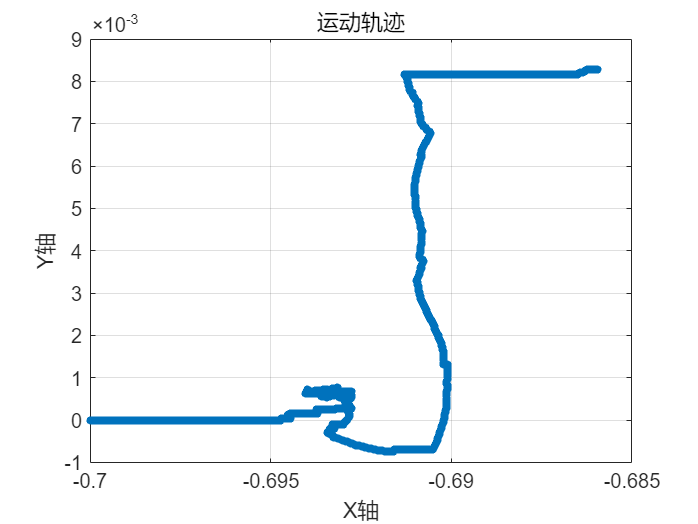

figure;
% 使用 plot 函数绘制运动轨迹
plot(xArray, yArray, '-o', 'LineWidth', 2, 'MarkerSize', 2);

% 添加标签和标题
xlabel('X轴');
ylabel('Y轴');
title('运动轨迹');
% 显示网格
grid on;

## 绘制速度和角度变化情况

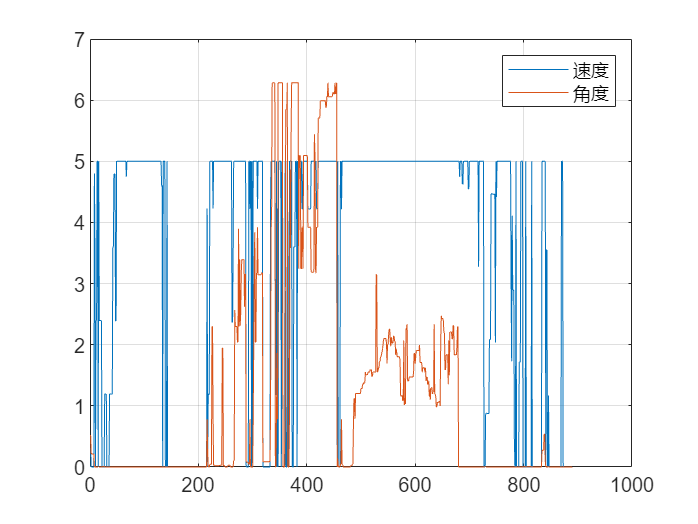

figure;
plot(vArray, '-', 'DisplayName', '速度');
hold on;
plot(thetaArray, '-', 'DisplayName', '角度');

legend('show');
grid on;
hold off;

## 绘制两个多普勒频移

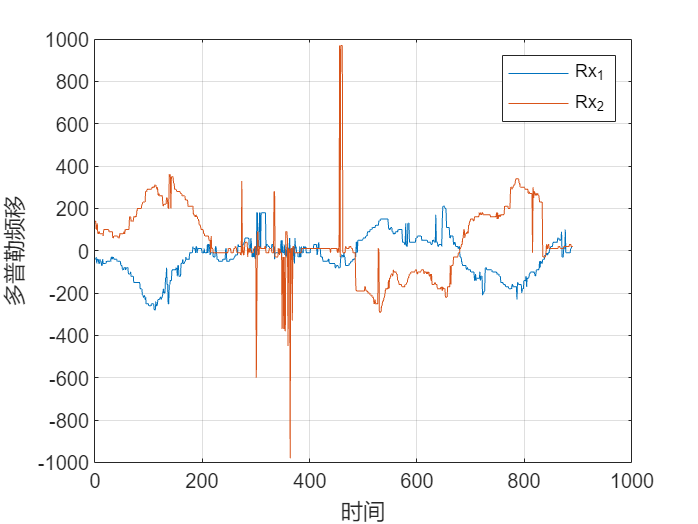

figure;
plot(f1Array, '-', 'DisplayName', 'Rx_1');
hold on;
plot(f2Array, '-', 'DisplayName', 'Rx_2');

% xlim([1,max_iter1]);
ylim([-1000,1000]);
xlabel('时间');
ylabel('多普勒频移');
legend('show');
grid on;
hold off;